clear all;
close all;
load("../step004-identify-transfer-function/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
tData= identifyTransferFunctionContinuousTimeResults.tData;
yDeg= identifyTransferFunctionContinuousTimeResults.yData;

GS= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
GS

GS =
  From input "u1" to output "y1":
          8496
  --------------------
  s^2 + 21.99 s + 7797
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "identData".
Fit to estimation data: 88.06%                        
FPE: 0.02961, MSE: 0.02682                            
 
Model Properties


Convert the continuous-time transfer function to a discrete-time state space model with sampling time delta_t:

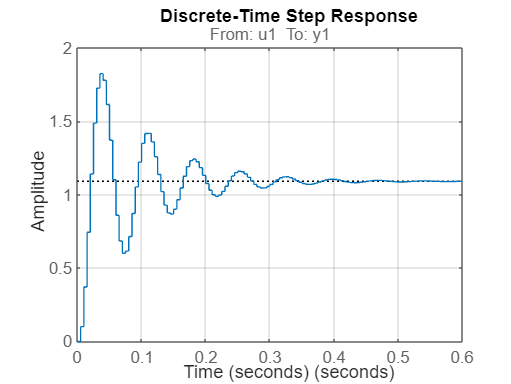

% Define the sample time (adjust Ts to your needs, e.g., Ts = 0.1)
delta_t = 0.005; 

% Convert the continuous-time transfer function to discrete-time state-space
sys_d = c2d(GS, delta_t, 'zoh');   % Zero-order hold discretization

% Simulate and plot the step response of the discrete-time system
step(sys_d)
title('Discrete-Time Step Response')
xlabel('Time (seconds)')
ylabel('Amplitude')
grid on